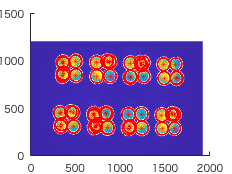

% このブロックでは，ファイバーの較正画像から32個の円を漏れなく検出することを目指します.
% 実行環境によって調整すべき変数は，較正画像pathであるFiberCalibrationImagePathです．
% すべての円を漏れなく検出できないとき調整すべき変数はimfindcircles(RadiusRenge, Sensitivity), numberです．
% 画像を読み込み，前処理を施します．
% FiberCalibrationImagePath = "/Volumes/experiment/results/X-ray/230704/Calibration/shot006.tif";
FiberCalibrationImagePath = "/Users/shinjirotakeda/Library/CloudStorage/OneDrive-TheUniversityofTokyo/Documents/SXR_Images/230712/PositionCheck.tif";
CalibrationImage = imread(FiberCalibrationImagePath);
CalibrationImage = wiener2(CalibrationImage,[10,10]);
CalibrationImage = imadjust(CalibrationImage);
% 円を検出します．range,sensitivity,method がパラメータです．
% この画像なら，range=[70,~], sensitivity=0.995がよさそう．[85,~]でも検知するけど，ちょっと大きめの円を取ってしまう
[centers,radii] = imfindcircles(CalibrationImage,[65,75],'Sensitivity',0.995,"Method","twostage");
% 検出した円をnumber個だけ描画します．このとき，numberは32個の円が全て含まれる程度に大きく設定します．
% numberに許される最大値はnumel(radii)で，TIF画像によりますがおよそ200程度ぽいです．優先度の低い円を考慮から外すためにnumberをある程度小さくする必要があります．
% こちらを整理前のcentersとします．numberを調整したので検出に漏れはありませんがダブりがあります．
figure;hold on;
number = 60;
imagesc(CalibrationImage);viscircles(centers(1:number,:),radii(1:number,:));plot(centers(1:number,1),centers(1:number,2),'*','Color','red');hold off;

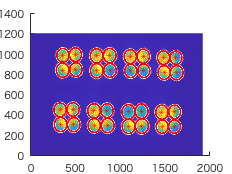


% ダブりで検出した円を整理します．
% 中心が近く同じ円を指すと判断されるものをgroupnumberでまとめます
% ここで，その判断基準であるcenter同士の距離の閾値(if r<80)は上手くいくようにTIF画像ごとに変える必要があります．
centers = [centers(1:number,:) radii(1:number) zeros([number,1])];
groupnumber = 1;
for i=1:number
    x1=centers(i,1);y1=centers(i,2);
    if centers(i,4) == 0
        for j=i:number
            x2=centers(j,1);y2=centers(j,2);
            r = sqrt((x1-x2)^2+(y1-y2)^2);
            if r < 80
                centers(j,4) = groupnumber;
            end
        end
        groupnumber = groupnumber + 1;
    end
end
% 同じgroupnumberをもつ円情報を統合し，ひとつにします．
% ただし同じ円を2回以上数えている場合は確度の最も高いものを採用します．
for i = 1:groupnumber-1
    [row0,~,~] = find(centers == i);
    if numel(row0) >1
        row = row0(1);
    else 
        row = row0;
    end
    center_mean_x = sum(centers(row,1))/numel(row);
    center_mean_y = sum(centers(row,2))/numel(row);
    radius_mean = sum(centers(row,3))/numel(row);
    centers(row0,:) = [];centers(end+1,:) = [center_mean_x,center_mean_y,radius_mean,i];
end
radii = centers(:,3);centers = centers(:,1:2);
% 整理後のcentersです．ただし時系列には整列されていません．
figure;hold on;imagesc(CalibrationImage);viscircles(centers,radii);plot(centers(:,1),centers(:,2),'*','Color','red');hold off;

% centersを時系列に整理します．
% まず横軸x座標を基準に並び替えます
centers = [centers radii];
[~,I] = sort(centers(:,1),'descend');
centers = centers(I,:);
% 次に横軸が近しい4つのデータの中で，縦軸を基準に並び替えます．
% これで，右上から左下に五十音表と同じ順に整理されます．
for i = 1:8
    range = 1+4*(i-1):1:4+4*(i-1);
    [~,I] = sort(centers(range,2),'descend');
    I = I + 4*(i-1);
    centers(range,:) = centers(I,:);
end
% 次にX線フィルタ種類と時系列順に整理します．
% X線フィルタは，右上を1，右下を2, 左上を3とします
% CentersTimeRaps(3,:,:)はX線フィルタ3の時系列[8 2]行列です．
% CentersTimeRaps(3,4,:)はX線フィルタ3の時系列4番目のxy座標です．
% 蛇順のため原始的なコードが入りますが，次のブロックで上手くいっていることが確かめられます．
CentersTimeRaps = zeros(4,8,3);
for i = 1:4
    if i==1 || i==2
    j = i-1;
    CentersTimeRaps(i,:,:) = centers([1+j,3+j,11+j, ...
        9+j,17+j,19+j,27+j,25+j],:);
    else
    j=i-3;
    CentersTimeRaps(i,:,:) = centers([5+j,7+j,15+j, ...
        13+j,21+j,23+j,31+j,29+j],:);    
    end
end

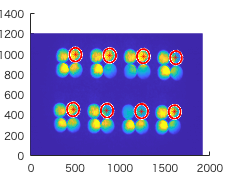

% 正しく整列できたかを確かめます
% まずX線フィルタ2の時系列を表示します
FileterNumber=1;
centers_number = squeeze(CentersTimeRaps(FileterNumber,:,1:2)); radii = CentersTimeRaps(FileterNumber,:,3);
figure;hold on;imagesc(CalibrationImage);viscircles(centers_number,radii);plot(centers_number(:,1),centers_number(:,2),'*','Color','red');hold off;

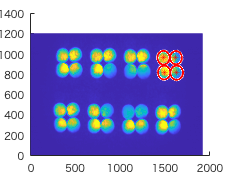

% 次に時系列4に値する4本のファイバを表示します
time = 1;
centers_time = squeeze(CentersTimeRaps(:,time,1:2)); radii = CentersTimeRaps(:,time,3);
figure;hold on;imagesc(CalibrationImage);viscircles(centers_time,radii);plot(centers_time(:,1),centers_time(:,2),'*','Color','red');hold off;